load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data3.mat')
map = Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map3.mat")
Map = occupancyMap(omap);

Data

RequiredMaps = 100000


ss = stateSpaceSE2

ss =   stateSpaceSE2 with properties:

                 Name: 'SE2'
          StateBounds: [3×2 double]
    NumStateVariables: 3
             WeightXY: 1
          WeightTheta: 0.1000


ss.StateBounds

ans =  -100.0000  100.0000
 -100.0000  100.0000
   -3.1416    3.1416


ss.StateBounds = [[0 50]; [0 50]; [-3.1416 3.1416]];
sv = validatorOccupancyMap(ss);



sv.Map = Map

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: Inf


sv.ValidationDistance = 0.0001

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: 1.0000e-04


ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];


planner = plannerRRT(ss,sv,MaxConnectionDistance=2);

rng(100, 'twister');
[pathObj, solvInf] = plan(planner, robot_pose, goal_pose)   

pathObj =   navPath with properties:

      StateSpace: [1×1 stateSpaceSE2]
          States: [16×3 double]
       NumStates: 16
    MaxNumStates: Inf


solvInf = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 63
    NumIterations: 111
         TreeData: [191×3 double]


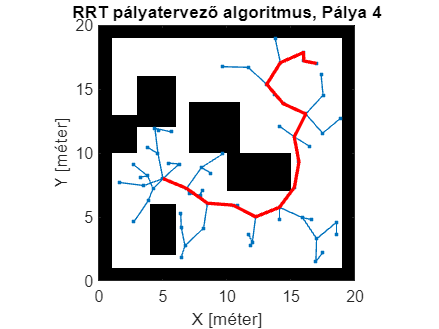



show(Map)
hold on
% Tree expansion
plot(solvInf.TreeData(:,1),solvInf.TreeData(:,2),'.-')
% Draw path
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2)
title("RRT pályatervező algoritmus, Pálya 4")
xlabel("X [méter]")
ylabel("Y [méter]")

pathObj.States(:,1)

ans =     5.0000
    6.8470
    8.4747
   10.4690
   12.2386
   14.0953
   15.2703
   15.6224
   15.2537
   16.1605


pathObj.States(:,2)

ans =     8.0000
    7.2343
    6.0778
    5.9263
    5.0119
    5.7529
    7.3321
    9.3001
   11.2658
   13.0479
